%% Part 3

## Question 1

WARNING SOPEN(EDF): Automated Overflowdetection not supported for EDF and BDF data, because 
   Physical Max/Min values of EDF/BDF data are not necessarily defining the dynamic range.
   For more information see: http://dx.doi.org/10.1016/S1388-2457(99)00172-8 (A. Schloegl et al. Quality Control ... Clin. Neurophysiol. 1999, Dec; 110(12): 2165 - 2170).
   A copy is available here, too: http://pub.ist.ac.at/~schloegl/publications/neurophys1999_2165.pdf 
 See also EEG2HIST: it's a tool to identify the saturation thresholds.
Warning SOPEN(BDF): File data_files/c30o30_s7_t1.bdf does not contain Status Channel - overflowdetection not supported!


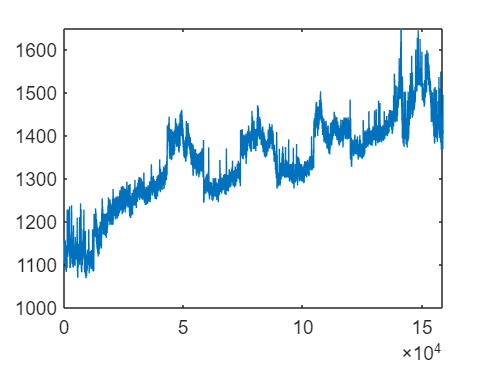

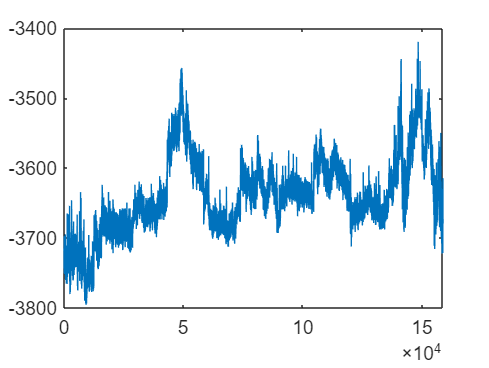

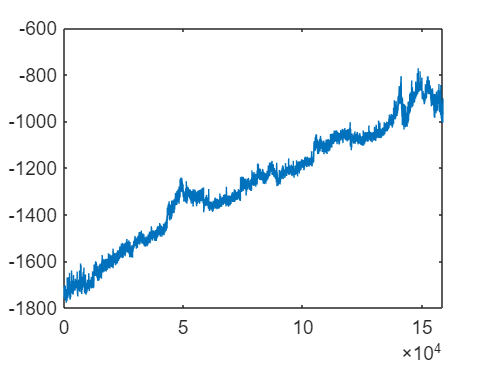

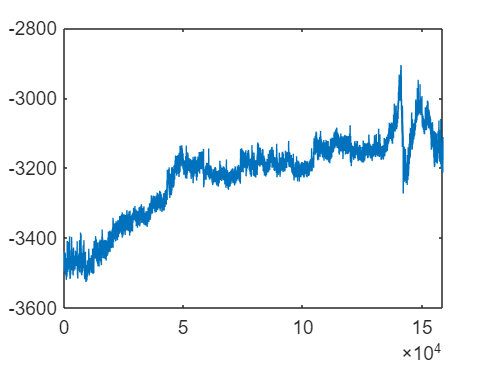

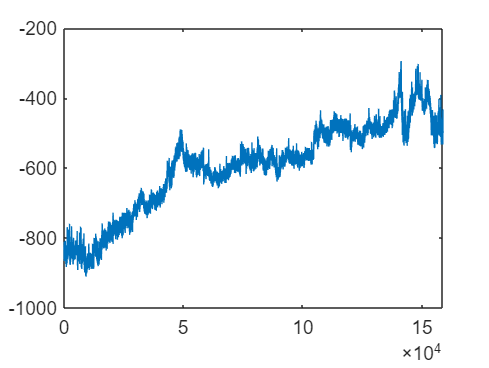

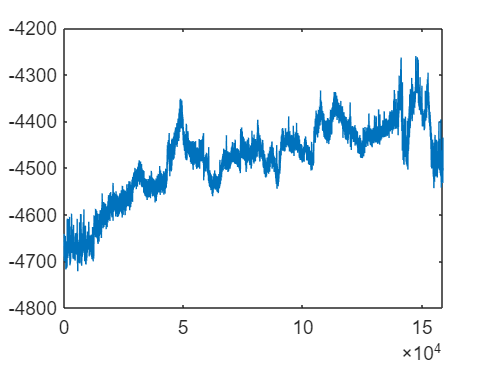

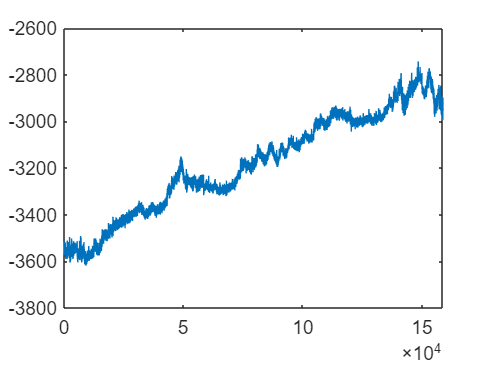

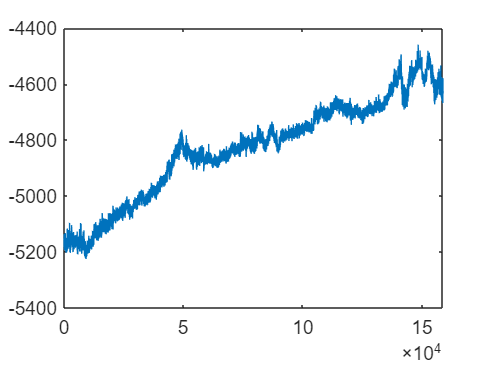

Found 9 triggers.


Extracted 4, 24 second epochs of each class from 


WARNING SOPEN(EDF): Automated Overflowdetection not supported for EDF and BDF data, because 
   Physical Max/Min values of EDF/BDF data are not necessarily defining the dynamic range.
   For more information see: http://dx.doi.org/10.1016/S1388-2457(99)00172-8 (A. Schloegl et al. Quality Control ... Clin. Neurophysiol. 1999, Dec; 110(12): 2165 - 2170).
   A copy is available here, too: http://pub.ist.ac.at/~schloegl/publications/neurophys1999_2165.pdf 
 See also EEG2HIST: it's a tool to identify the saturation thresholds.
Warning SOPEN(BDF): File data_files/c30o30_s7_t2.bdf does not contain Status Channel - overflowdetection not supported!


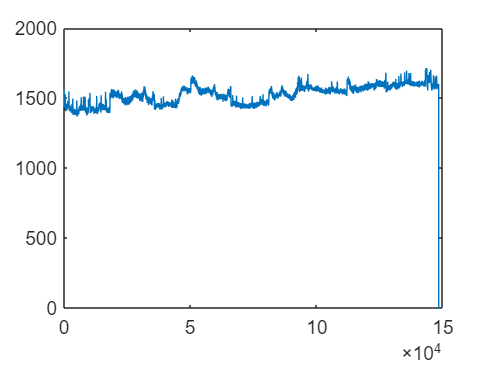

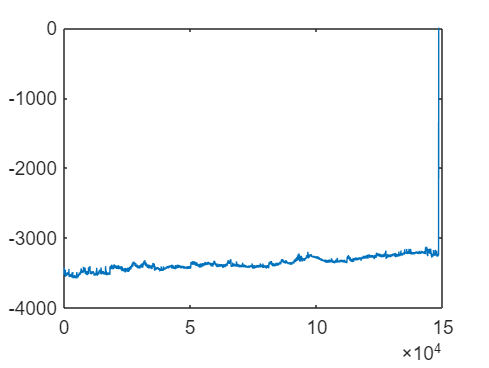

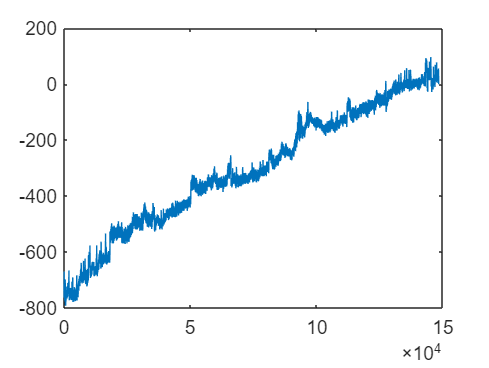

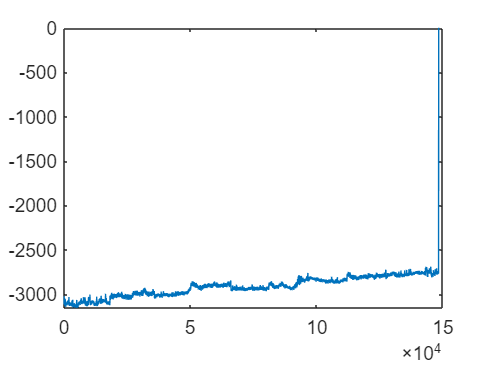

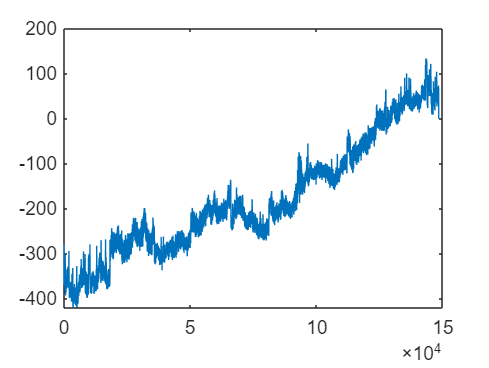

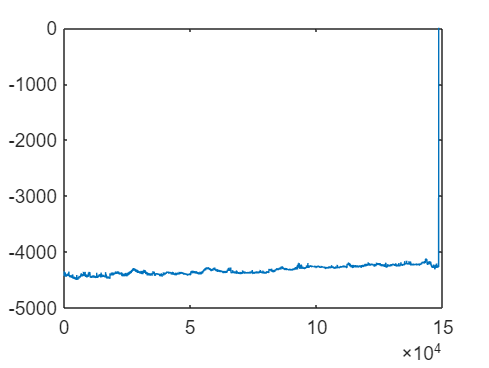

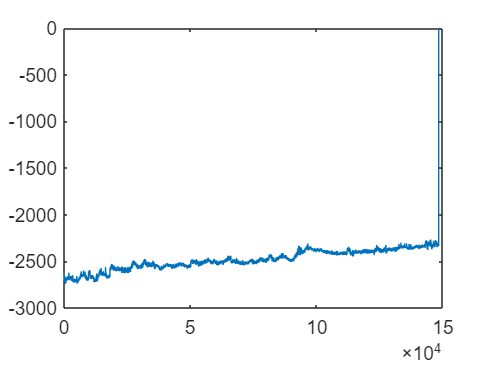

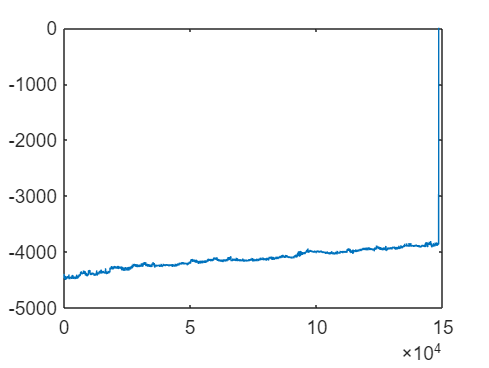

Found 9 triggers.


Extracted 4, 24 second epochs of each class from 


% Load each file and extract epochs, put in relevant structures
%
% Define the EEG file(s) of interest
fname = {'data_files/c30o30_s7_t1.bdf', 'data_files/c30o30_s7_t2.bdf'};
% Initialise epoch counter
N_epochs = 0;
for fi=1:length(fname)
 % Load the EEG file (fname{fi}). Note the semicolon to surpress echo
 % of S and HDR to the command window. Don't worry about warnings
 % concerning overflow detection or the lack of a status channel.
 %
 % For more info type:
 %
 % >> help sload
 %
 [S, HDR] = sload(fname{fi});

 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
 % Extract triggers

for i=1:17
figure
plot(S(:,i))
end

Fs = 512;
% Implements supplementary_code/part_2/extract_epochs.m
% Find length of signal
L = length(S);
% Differentiate trigger channel
delta_trig = S(2:L,17) - S(1:L-1,17);
% Look for rising edges
trig = find(delta_trig>0);
% Debounce if required
% I.e. remove spurious short triggers, if any
% these can occur when using a manual switch-based trigger
% e.g. look at the trigger channel in 'data_files/c30o30_s4_t1.bdf'
T_debounce = 0.5; % (in seconds) - set as desired
dt_trig = trig(2:end) - trig(1:end-1);
delete_short_trigs = find(dt_trig < Fs*T_debounce) + 1;
trig(delete_short_trigs) = [];
% How many triggers were extracted in total, after debouncing?
N_trigs = length(trig)-1;
% Ensure we have an odd number of triggers (ignore final incomplete
% epoch if not).
% Trigger 1 = start of experiment
% Triggers 2, 4, 6, 8... (2k) = eyes closed
% Triggers 3, 5, 7, 9... (2k+1) = eyes open
if mod(N_trigs, 2) == 0
 N_trigs = N_trigs - 1;
end
disp(cell2mat(strcat({'Found '}, int2str(N_trigs), {' triggers.'})));

%N_epochs = N_trigs;

% Discard 2 seconds of data before & after each cue
discard = 2*Fs;
% Extract each epoch of data and store in the relevant structure for
% each class
% - eyes_closed (even triggers)
% - eyes_open (odd triggers)

for i=1:N_epochs/2 % insert your own code here to extract the triggers
 % (see previous part of the lab)
 eyes_closed{i} = S(trig(2*i)+discard:trig(2*i+1)-discard,1:16);
 eyes_open{i} = S(trig(2*i+1)+discard:trig(2*i+2)-discard,1:16);
end

 % Discard 2 seconds of data before & after each cue
 discard = 2*Fs;
 % Extract each epoch of data and store in the relevant structure for
 % each class
 % - ec: Eyes closed
 % - eo: Eyes open
 this_epochs = 0;
 Epoch_length = 24; % in seconds
 samples = Epoch_length*Fs;
 for i=1:N_trigs/2
 ec_extracted{i} = S(trig(2*i)+discard:trig(2*i+1)-discard,1:16);
 eo_extracted{i} = S(trig(2*i+1)+discard:trig(2*i+2)-discard,1:16);
 maxlen = min(length(ec_extracted{i}), length(eo_extracted{i}));
 N_loop = floor(maxlen / samples);
 for j = 1:N_loop
     N_epochs = N_epochs + 1;
 %throw an error % if you have copied code from "Part 2"
 % make sure to delete "N_epochs = N_trigs"
 % from your previous code, otherwise it will
 % mess this up - you now want to count more
% epochs as you discover them in additional
 % files
 this_epochs = this_epochs + 1;
 ec{N_epochs} = ec_extracted{i}((j-1)*samples+1:j*samples,:);
 eo{N_epochs} = eo_extracted{i}((j-1)*samples+1:j*samples,:);
 end
 end
 disp(cell2mat(strcat({'Extracted '}, int2str(this_epochs), {', '},...
 int2str(Epoch_length), {' second epochs of each class from '})));
end

disp(cell2mat(strcat({'Extracted a total of '}, int2str(N_epochs),...
 {', '}, int2str(Epoch_length), {' second epochs of each class.'})));

Extracted a total of 8, 24 second epochs of each class.


## Question 2

% Plot FFT of raw data eo = eyes open
eo_fft = fft(eo{1});
% Electrode montage on scalp
montage = [-1 -1 1 -1 -1; 2 3 4 5 6; 7 8 9 10 11; 12 13 14 15 16];

electrode_labels = {'Fz', 'FC3', 'FC1', 'FCz', 'FC2', 'FC4','C3', 'C1',... 
                       'Cz', 'C2', 'C4','CP3', 'CP1', 'CPz', 'CP2', 'CP4'};
% Create a new figure (or select an exisiting one if you prefer)
figure

% Iterate through each row (j) and column(i) of the montage matrix that
% will form your subplot figure
for j=1:4
    for i=1:5
        % Only create plots for electrodes that exist (ignore -1 values)
        if montage(j, i) > 0
            % which electrode is at this location in the montage matrix?
            electrode = montage(j, i);
            % select the correct (row, colum) --> what does the number 5 do
            % here?
            subplot(4, 5, i+(5*(j-1)))
            
            % plot something for the current electrode. You can plot
            % whatever data you want here, but for example:
            plotFFT2(eo_fft(:,electrode), Fs)
            
            % Set axes limits if necessary, e.g.
            ylim([0 5])
            xlim([0 40])
            
            % Label each subplot with the corresponding electrode poistion
            title(electrode_labels{electrode})
            
            % Label the axes for the bottom left plot only (to prevent the
            % figure getting too crowded and illegible)
            if i == 1 && j == 4
                xlabel('Frequency (Hz)');
                ylabel('FFT (uV)')
            end
        end
    end
end

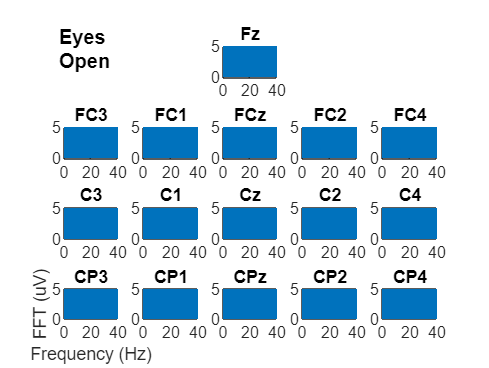


% Add a title to the entire plot - play around, as required
annotation('textbox', [0.1,0.75, 0.2, 0.2], 'String', 'Eyes Open',...
                                'FontWeight', 'bold', 'LineStyle', 'none')

## Question 3 and 4

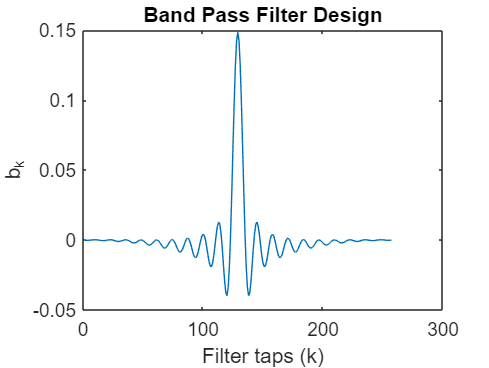

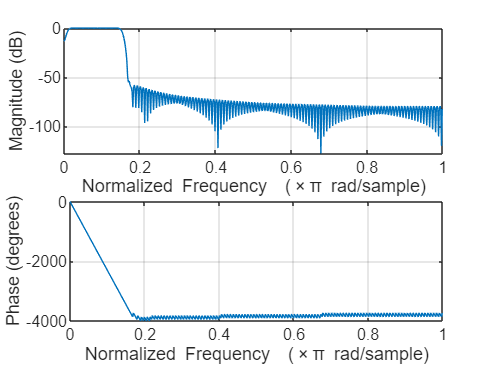

% Implements supplementary_code/part_3/calc_psd.m
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Pre-filter data and calculate PSD for every epoch and every electrode.
% The PSD should be resampled into 2Hz ‘bins’
% Band pass 2-40 Hz (use the filter you designed earlier)
b_bp = band_pass(Fs);

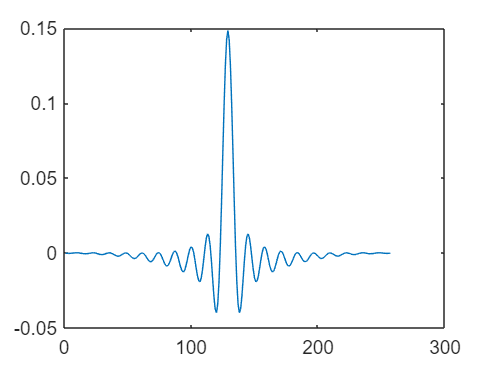

plot(b_bp)

% Iterate through every extracted epoch
for i = 1:N_epochs

 % Iterate through each electrode channel (Ei)
 for Ei = 1:16

 % Apply bandpass filter to eyes open
 eo_bp(:,:,Ei) = filter(b_bp, 1, eo{i}(:,Ei));

 %??? NOW FILTER EYES CLOSED ???%
 ec_bp(:,:,Ei) = filter(b_bp, 1, ec{i}(:,Ei)); 

 % Calculate PSD for Ei using the Welch method
 [psd_eo, freqs_eo] = pwelch(eo_bp(:,:,Ei), [], [], [], Fs);
 N_psd_eo = length(psd_eo) - 1;
 temp_psd_eo = reshape(psd_eo(1:N_psd_eo), N_psd_eo/(Fs / (2 * 2)), []);
 eo_psd_2hz(:,i,Ei) = mean(temp_psd_eo,1);  
 
 %??? NOW calculate PSD EYES CLOSED ???%
 [psd_ec, freqs_ec] = pwelch(ec_bp(:,:,Ei), [], [], [], Fs);
 N_psd_ec = length(psd_ec) - 1;
 temp_psd_ec = reshape(psd_ec(1:N_psd_ec), N_psd_ec/(Fs / (2 * 2)), []);
 ec_psd_2hz(:,i, Ei) = mean(temp_psd_ec, 1)

 end
end

ec_psd_2hz = 	1.0e+04 *

    3.4473
    0.0008
    0.0005
    0.0003
    0.0012
    0.0010
    0.0001
    0.0001
    0.0001
    0.0001


ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473
    0.0008
    0.0005
    0.0003
    0.0012
    0.0010
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473
    0.0008
    0.0005
    0.0003
    0.0012
    0.0010
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473
    0.0008
    0.0005
    0.0003
    0.0012
    0.0010
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473
    0.0008
    0.0005
    0.0003
    0.0012
    0.0010
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473
    0.0008
    0.0005
    0.0003
    0.0012
    0.0010
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473
    0.0008
    0.0005
    0.0003
    0.0012
    0.0010
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473
    0.0008
    0.0005
    0.0003
    0.0012
    0.0010
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473
    0.0008
    0.0005
    0.0003
    0.0012
    0.0010
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473
    0.0008
    0.0005
    0.0003
    0.0012
    0.0010
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473
    0.0008
    0.0005
    0.0003
    0.0012
    0.0010
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473
    0.0008
    0.0005
    0.0003
    0.0012
    0.0010
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473
    0.0008
    0.0005
    0.0003
    0.0012
    0.0010
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473
    0.0008
    0.0005
    0.0003
    0.0012
    0.0010
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473
    0.0008
    0.0005
    0.0003
    0.0012
    0.0010
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473
    0.0008
    0.0005
    0.0003
    0.0012
    0.0010
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005
    0.0008    0.0009
    0.0005    0.0006
    0.0003    0.0005
    0.0012    0.0010
    0.0010    0.0014
    0.0001    0.0002
    0.0001    0.0001
    0.0001    0.0001
    0.0001    0.0001
    0.0001    0.0001
    0.0001    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005
    0.0008    0.0009
    0.0005    0.0006
    0.0003    0.0005
    0.0012    0.0010
    0.0010    0.0014
    0.0001    0.0002
    0.0001    0.0001
    0.0001    0.0001
    0.0001    0.0001
    0.0001    0.0001
    0.0001    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005
    0.0008    0.0009
    0.0005    0.0006
    0.0003    0.0005
    0.0012    0.0010
    0.0010    0.0014
    0.0001    0.0002
    0.0001    0.0001
    0.0001    0.0001
    0.0001    0.0001
    0.0001    0.0001
    0.0001    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005
    0.0008    0.0009
    0.0005    0.0006
    0.0003    0.0005
    0.0012    0.0010
    0.0010    0.0014
    0.0001    0.0002
    0.0001    0.0001
    0.0001    0.0001
    0.0001    0.0001
    0.0001    0.0001
    0.0001    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005
    0.0008    0.0009
    0.0005    0.0006
    0.0003    0.0005
    0.0012    0.0010
    0.0010    0.0014
    0.0001    0.0002
    0.0001    0.0001
    0.0001    0.0001
    0.0001    0.0001
    0.0001    0.0001
    0.0001    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005
    0.0008    0.0009
    0.0005    0.0006
    0.0003    0.0005
    0.0012    0.0010
    0.0010    0.0014
    0.0001    0.0002
    0.0001    0.0001
    0.0001    0.0001
    0.0001    0.0001
    0.0001    0.0001
    0.0001    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005
    0.0008    0.0009
    0.0005    0.0006
    0.0003    0.0005
    0.0012    0.0010
    0.0010    0.0014
    0.0001    0.0002
    0.0001    0.0001
    0.0001    0.0001
    0.0001    0.0001
    0.0001    0.0001
    0.0001    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005
    0.0008    0.0009
    0.0005    0.0006
    0.0003    0.0005
    0.0012    0.0010
    0.0010    0.0014
    0.0001    0.0002
    0.0001    0.0001
    0.0001    0.0001
    0.0001    0.0001
    0.0001    0.0001
    0.0001    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005
    0.0008    0.0009
    0.0005    0.0006
    0.0003    0.0005
    0.0012    0.0010
    0.0010    0.0014
    0.0001    0.0002
    0.0001    0.0001
    0.0001    0.0001
    0.0001    0.0001
    0.0001    0.0001
    0.0001    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005
    0.0008    0.0009
    0.0005    0.0006
    0.0003    0.0005
    0.0012    0.0010
    0.0010    0.0014
    0.0001    0.0002
    0.0001    0.0001
    0.0001    0.0001
    0.0001    0.0001
    0.0001    0.0001
    0.0001    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005
    0.0008    0.0009
    0.0005    0.0006
    0.0003    0.0005
    0.0012    0.0010
    0.0010    0.0014
    0.0001    0.0002
    0.0001    0.0001
    0.0001    0.0001
    0.0001    0.0001
    0.0001    0.0001
    0.0001    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005
    0.0008    0.0009
    0.0005    0.0006
    0.0003    0.0005
    0.0012    0.0010
    0.0010    0.0014
    0.0001    0.0002
    0.0001    0.0001
    0.0001    0.0001
    0.0001    0.0001
    0.0001    0.0001
    0.0001    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005
    0.0008    0.0009
    0.0005    0.0006
    0.0003    0.0005
    0.0012    0.0010
    0.0010    0.0014
    0.0001    0.0002
    0.0001    0.0001
    0.0001    0.0001
    0.0001    0.0001
    0.0001    0.0001
    0.0001    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005
    0.0008    0.0009
    0.0005    0.0006
    0.0003    0.0005
    0.0012    0.0010
    0.0010    0.0014
    0.0001    0.0002
    0.0001    0.0001
    0.0001    0.0001
    0.0001    0.0001
    0.0001    0.0001
    0.0001    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005
    0.0008    0.0009
    0.0005    0.0006
    0.0003    0.0005
    0.0012    0.0010
    0.0010    0.0014
    0.0001    0.0002
    0.0001    0.0001
    0.0001    0.0001
    0.0001    0.0001
    0.0001    0.0001
    0.0001    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005
    0.0008    0.0009
    0.0005    0.0006
    0.0003    0.0005
    0.0012    0.0010
    0.0010    0.0014
    0.0001    0.0002
    0.0001    0.0001
    0.0001    0.0001
    0.0001    0.0001
    0.0001    0.0001
    0.0001    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649
    0.0008    0.0009    0.0010
    0.0005    0.0006    0.0006
    0.0003    0.0005    0.0004
    0.0012    0.0010    0.0012
    0.0010    0.0014    0.0009
    0.0001    0.0002    0.0002
    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000  

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649
    0.0008    0.0009    0.0010
    0.0005    0.0006    0.0006
    0.0003    0.0005    0.0004
    0.0012    0.0010    0.0012
    0.0010    0.0014    0.0009
    0.0001    0.0002    0.0002
    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000  

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649
    0.0008    0.0009    0.0010
    0.0005    0.0006    0.0006
    0.0003    0.0005    0.0004
    0.0012    0.0010    0.0012
    0.0010    0.0014    0.0009
    0.0001    0.0002    0.0002
    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000  

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649
    0.0008    0.0009    0.0010
    0.0005    0.0006    0.0006
    0.0003    0.0005    0.0004
    0.0012    0.0010    0.0012
    0.0010    0.0014    0.0009
    0.0001    0.0002    0.0002
    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000  

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649
    0.0008    0.0009    0.0010
    0.0005    0.0006    0.0006
    0.0003    0.0005    0.0004
    0.0012    0.0010    0.0012
    0.0010    0.0014    0.0009
    0.0001    0.0002    0.0002
    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000  

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649
    0.0008    0.0009    0.0010
    0.0005    0.0006    0.0006
    0.0003    0.0005    0.0004
    0.0012    0.0010    0.0012
    0.0010    0.0014    0.0009
    0.0001    0.0002    0.0002
    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000  

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649
    0.0008    0.0009    0.0010
    0.0005    0.0006    0.0006
    0.0003    0.0005    0.0004
    0.0012    0.0010    0.0012
    0.0010    0.0014    0.0009
    0.0001    0.0002    0.0002
    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000  

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649
    0.0008    0.0009    0.0010
    0.0005    0.0006    0.0006
    0.0003    0.0005    0.0004
    0.0012    0.0010    0.0012
    0.0010    0.0014    0.0009
    0.0001    0.0002    0.0002
    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000  

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649
    0.0008    0.0009    0.0010
    0.0005    0.0006    0.0006
    0.0003    0.0005    0.0004
    0.0012    0.0010    0.0012
    0.0010    0.0014    0.0009
    0.0001    0.0002    0.0002
    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000  

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649
    0.0008    0.0009    0.0010
    0.0005    0.0006    0.0006
    0.0003    0.0005    0.0004
    0.0012    0.0010    0.0012
    0.0010    0.0014    0.0009
    0.0001    0.0002    0.0002
    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000  

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649
    0.0008    0.0009    0.0010
    0.0005    0.0006    0.0006
    0.0003    0.0005    0.0004
    0.0012    0.0010    0.0012
    0.0010    0.0014    0.0009
    0.0001    0.0002    0.0002
    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000  

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649
    0.0008    0.0009    0.0010
    0.0005    0.0006    0.0006
    0.0003    0.0005    0.0004
    0.0012    0.0010    0.0012
    0.0010    0.0014    0.0009
    0.0001    0.0002    0.0002
    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000  

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649
    0.0008    0.0009    0.0010
    0.0005    0.0006    0.0006
    0.0003    0.0005    0.0004
    0.0012    0.0010    0.0012
    0.0010    0.0014    0.0009
    0.0001    0.0002    0.0002
    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000  

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649
    0.0008    0.0009    0.0010
    0.0005    0.0006    0.0006
    0.0003    0.0005    0.0004
    0.0012    0.0010    0.0012
    0.0010    0.0014    0.0009
    0.0001    0.0002    0.0002
    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000  

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649
    0.0008    0.0009    0.0010
    0.0005    0.0006    0.0006
    0.0003    0.0005    0.0004
    0.0012    0.0010    0.0012
    0.0010    0.0014    0.0009
    0.0001    0.0002    0.0002
    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000  

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649
    0.0008    0.0009    0.0010
    0.0005    0.0006    0.0006
    0.0003    0.0005    0.0004
    0.0012    0.0010    0.0012
    0.0010    0.0014    0.0009
    0.0001    0.0002    0.0002
    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000  

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136
    0.0008    0.0009    0.0010    0.0011
    0.0005    0.0006    0.0006    0.0006
    0.0003    0.0005    0.0004    0.0005
    0.0012    0.0010    0.0012    0.0011
    0.0010    0.0014    0.0009    0.0008
    0.0001    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.000

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136
    0.0008    0.0009    0.0010    0.0011
    0.0005    0.0006    0.0006    0.0006
    0.0003    0.0005    0.0004    0.0005
    0.0012    0.0010    0.0012    0.0011
    0.0010    0.0014    0.0009    0.0008
    0.0001    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.000

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136
    0.0008    0.0009    0.0010    0.0011
    0.0005    0.0006    0.0006    0.0006
    0.0003    0.0005    0.0004    0.0005
    0.0012    0.0010    0.0012    0.0011
    0.0010    0.0014    0.0009    0.0008
    0.0001    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.000

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136
    0.0008    0.0009    0.0010    0.0011
    0.0005    0.0006    0.0006    0.0006
    0.0003    0.0005    0.0004    0.0005
    0.0012    0.0010    0.0012    0.0011
    0.0010    0.0014    0.0009    0.0008
    0.0001    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.000

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136
    0.0008    0.0009    0.0010    0.0011
    0.0005    0.0006    0.0006    0.0006
    0.0003    0.0005    0.0004    0.0005
    0.0012    0.0010    0.0012    0.0011
    0.0010    0.0014    0.0009    0.0008
    0.0001    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.000

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136
    0.0008    0.0009    0.0010    0.0011
    0.0005    0.0006    0.0006    0.0006
    0.0003    0.0005    0.0004    0.0005
    0.0012    0.0010    0.0012    0.0011
    0.0010    0.0014    0.0009    0.0008
    0.0001    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.000

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136
    0.0008    0.0009    0.0010    0.0011
    0.0005    0.0006    0.0006    0.0006
    0.0003    0.0005    0.0004    0.0005
    0.0012    0.0010    0.0012    0.0011
    0.0010    0.0014    0.0009    0.0008
    0.0001    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.000

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136
    0.0008    0.0009    0.0010    0.0011
    0.0005    0.0006    0.0006    0.0006
    0.0003    0.0005    0.0004    0.0005
    0.0012    0.0010    0.0012    0.0011
    0.0010    0.0014    0.0009    0.0008
    0.0001    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.000

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136
    0.0008    0.0009    0.0010    0.0011
    0.0005    0.0006    0.0006    0.0006
    0.0003    0.0005    0.0004    0.0005
    0.0012    0.0010    0.0012    0.0011
    0.0010    0.0014    0.0009    0.0008
    0.0001    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.000

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136
    0.0008    0.0009    0.0010    0.0011
    0.0005    0.0006    0.0006    0.0006
    0.0003    0.0005    0.0004    0.0005
    0.0012    0.0010    0.0012    0.0011
    0.0010    0.0014    0.0009    0.0008
    0.0001    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.000

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136
    0.0008    0.0009    0.0010    0.0011
    0.0005    0.0006    0.0006    0.0006
    0.0003    0.0005    0.0004    0.0005
    0.0012    0.0010    0.0012    0.0011
    0.0010    0.0014    0.0009    0.0008
    0.0001    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.000

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136
    0.0008    0.0009    0.0010    0.0011
    0.0005    0.0006    0.0006    0.0006
    0.0003    0.0005    0.0004    0.0005
    0.0012    0.0010    0.0012    0.0011
    0.0010    0.0014    0.0009    0.0008
    0.0001    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.000

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136
    0.0008    0.0009    0.0010    0.0011
    0.0005    0.0006    0.0006    0.0006
    0.0003    0.0005    0.0004    0.0005
    0.0012    0.0010    0.0012    0.0011
    0.0010    0.0014    0.0009    0.0008
    0.0001    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.000

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136
    0.0008    0.0009    0.0010    0.0011
    0.0005    0.0006    0.0006    0.0006
    0.0003    0.0005    0.0004    0.0005
    0.0012    0.0010    0.0012    0.0011
    0.0010    0.0014    0.0009    0.0008
    0.0001    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.000

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136
    0.0008    0.0009    0.0010    0.0011
    0.0005    0.0006    0.0006    0.0006
    0.0003    0.0005    0.0004    0.0005
    0.0012    0.0010    0.0012    0.0011
    0.0010    0.0014    0.0009    0.0008
    0.0001    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.000

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136
    0.0008    0.0009    0.0010    0.0011
    0.0005    0.0006    0.0006    0.0006
    0.0003    0.0005    0.0004    0.0005
    0.0012    0.0010    0.0012    0.0011
    0.0010    0.0014    0.0009    0.0008
    0.0001    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.000

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474
    0.0008    0.0009    0.0010    0.0011    0.0011
    0.0005    0.0006    0.0006    0.0006    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006
    0.0012    0.0010    0.0012    0.0011    0.0016
    0.0010    0.0014    0.0009    0.0008    0.0010
    0.0001    0.0002    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474
    0.0008    0.0009    0.0010    0.0011    0.0011
    0.0005    0.0006    0.0006    0.0006    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006
    0.0012    0.0010    0.0012    0.0011    0.0016
    0.0010    0.0014    0.0009    0.0008    0.0010
    0.0001    0.0002    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474
    0.0008    0.0009    0.0010    0.0011    0.0011
    0.0005    0.0006    0.0006    0.0006    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006
    0.0012    0.0010    0.0012    0.0011    0.0016
    0.0010    0.0014    0.0009    0.0008    0.0010
    0.0001    0.0002    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474
    0.0008    0.0009    0.0010    0.0011    0.0011
    0.0005    0.0006    0.0006    0.0006    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006
    0.0012    0.0010    0.0012    0.0011    0.0016
    0.0010    0.0014    0.0009    0.0008    0.0010
    0.0001    0.0002    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474
    0.0008    0.0009    0.0010    0.0011    0.0011
    0.0005    0.0006    0.0006    0.0006    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006
    0.0012    0.0010    0.0012    0.0011    0.0016
    0.0010    0.0014    0.0009    0.0008    0.0010
    0.0001    0.0002    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474
    0.0008    0.0009    0.0010    0.0011    0.0011
    0.0005    0.0006    0.0006    0.0006    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006
    0.0012    0.0010    0.0012    0.0011    0.0016
    0.0010    0.0014    0.0009    0.0008    0.0010
    0.0001    0.0002    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474
    0.0008    0.0009    0.0010    0.0011    0.0011
    0.0005    0.0006    0.0006    0.0006    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006
    0.0012    0.0010    0.0012    0.0011    0.0016
    0.0010    0.0014    0.0009    0.0008    0.0010
    0.0001    0.0002    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474
    0.0008    0.0009    0.0010    0.0011    0.0011
    0.0005    0.0006    0.0006    0.0006    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006
    0.0012    0.0010    0.0012    0.0011    0.0016
    0.0010    0.0014    0.0009    0.0008    0.0010
    0.0001    0.0002    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474
    0.0008    0.0009    0.0010    0.0011    0.0011
    0.0005    0.0006    0.0006    0.0006    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006
    0.0012    0.0010    0.0012    0.0011    0.0016
    0.0010    0.0014    0.0009    0.0008    0.0010
    0.0001    0.0002    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474
    0.0008    0.0009    0.0010    0.0011    0.0011
    0.0005    0.0006    0.0006    0.0006    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006
    0.0012    0.0010    0.0012    0.0011    0.0016
    0.0010    0.0014    0.0009    0.0008    0.0010
    0.0001    0.0002    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474
    0.0008    0.0009    0.0010    0.0011    0.0011
    0.0005    0.0006    0.0006    0.0006    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006
    0.0012    0.0010    0.0012    0.0011    0.0016
    0.0010    0.0014    0.0009    0.0008    0.0010
    0.0001    0.0002    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474
    0.0008    0.0009    0.0010    0.0011    0.0011
    0.0005    0.0006    0.0006    0.0006    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006
    0.0012    0.0010    0.0012    0.0011    0.0016
    0.0010    0.0014    0.0009    0.0008    0.0010
    0.0001    0.0002    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474
    0.0008    0.0009    0.0010    0.0011    0.0011
    0.0005    0.0006    0.0006    0.0006    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006
    0.0012    0.0010    0.0012    0.0011    0.0016
    0.0010    0.0014    0.0009    0.0008    0.0010
    0.0001    0.0002    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474
    0.0008    0.0009    0.0010    0.0011    0.0011
    0.0005    0.0006    0.0006    0.0006    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006
    0.0012    0.0010    0.0012    0.0011    0.0016
    0.0010    0.0014    0.0009    0.0008    0.0010
    0.0001    0.0002    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474
    0.0008    0.0009    0.0010    0.0011    0.0011
    0.0005    0.0006    0.0006    0.0006    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006
    0.0012    0.0010    0.0012    0.0011    0.0016
    0.0010    0.0014    0.0009    0.0008    0.0010
    0.0001    0.0002    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474
    0.0008    0.0009    0.0010    0.0011    0.0011
    0.0005    0.0006    0.0006    0.0006    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006
    0.0012    0.0010    0.0012    0.0011    0.0016
    0.0010    0.0014    0.0009    0.0008    0.0010
    0.0001    0.0002    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474    5.6277
    0.0008    0.0009    0.0010    0.0011    0.0011    0.0012
    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006    0.0005
    0.0012    0.0010    0.0012    0.0011    0.0016    0.0007
    0.0010    0.0014    0.0009    0.0008    0.0010    0.0011
    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474    5.6277
    0.0008    0.0009    0.0010    0.0011    0.0011    0.0012
    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006    0.0005
    0.0012    0.0010    0.0012    0.0011    0.0016    0.0007
    0.0010    0.0014    0.0009    0.0008    0.0010    0.0011
    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474    5.6277
    0.0008    0.0009    0.0010    0.0011    0.0011    0.0012
    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006    0.0005
    0.0012    0.0010    0.0012    0.0011    0.0016    0.0007
    0.0010    0.0014    0.0009    0.0008    0.0010    0.0011
    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474    5.6277
    0.0008    0.0009    0.0010    0.0011    0.0011    0.0012
    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006    0.0005
    0.0012    0.0010    0.0012    0.0011    0.0016    0.0007
    0.0010    0.0014    0.0009    0.0008    0.0010    0.0011
    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474    5.6277
    0.0008    0.0009    0.0010    0.0011    0.0011    0.0012
    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006    0.0005
    0.0012    0.0010    0.0012    0.0011    0.0016    0.0007
    0.0010    0.0014    0.0009    0.0008    0.0010    0.0011
    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474    5.6277
    0.0008    0.0009    0.0010    0.0011    0.0011    0.0012
    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006    0.0005
    0.0012    0.0010    0.0012    0.0011    0.0016    0.0007
    0.0010    0.0014    0.0009    0.0008    0.0010    0.0011
    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474    5.6277
    0.0008    0.0009    0.0010    0.0011    0.0011    0.0012
    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006    0.0005
    0.0012    0.0010    0.0012    0.0011    0.0016    0.0007
    0.0010    0.0014    0.0009    0.0008    0.0010    0.0011
    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474    5.6277
    0.0008    0.0009    0.0010    0.0011    0.0011    0.0012
    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006    0.0005
    0.0012    0.0010    0.0012    0.0011    0.0016    0.0007
    0.0010    0.0014    0.0009    0.0008    0.0010    0.0011
    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474    5.6277
    0.0008    0.0009    0.0010    0.0011    0.0011    0.0012
    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006    0.0005
    0.0012    0.0010    0.0012    0.0011    0.0016    0.0007
    0.0010    0.0014    0.0009    0.0008    0.0010    0.0011
    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474    5.6277
    0.0008    0.0009    0.0010    0.0011    0.0011    0.0012
    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006    0.0005
    0.0012    0.0010    0.0012    0.0011    0.0016    0.0007
    0.0010    0.0014    0.0009    0.0008    0.0010    0.0011
    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474    5.6277
    0.0008    0.0009    0.0010    0.0011    0.0011    0.0012
    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006    0.0005
    0.0012    0.0010    0.0012    0.0011    0.0016    0.0007
    0.0010    0.0014    0.0009    0.0008    0.0010    0.0011
    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474    5.6277
    0.0008    0.0009    0.0010    0.0011    0.0011    0.0012
    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006    0.0005
    0.0012    0.0010    0.0012    0.0011    0.0016    0.0007
    0.0010    0.0014    0.0009    0.0008    0.0010    0.0011
    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474    5.6277
    0.0008    0.0009    0.0010    0.0011    0.0011    0.0012
    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006    0.0005
    0.0012    0.0010    0.0012    0.0011    0.0016    0.0007
    0.0010    0.0014    0.0009    0.0008    0.0010    0.0011
    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474    5.6277
    0.0008    0.0009    0.0010    0.0011    0.0011    0.0012
    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006    0.0005
    0.0012    0.0010    0.0012    0.0011    0.0016    0.0007
    0.0010    0.0014    0.0009    0.0008    0.0010    0.0011
    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474    5.6277
    0.0008    0.0009    0.0010    0.0011    0.0011    0.0012
    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006    0.0005
    0.0012    0.0010    0.0012    0.0011    0.0016    0.0007
    0.0010    0.0014    0.0009    0.0008    0.0010    0.0011
    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474    5.6277
    0.0008    0.0009    0.0010    0.0011    0.0011    0.0012
    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006    0.0005
    0.0012    0.0010    0.0012    0.0011    0.0016    0.0007
    0.0010    0.0014    0.0009    0.0008    0.0010    0.0011
    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474    5.6277    5.4910
    0.0008    0.0009    0.0010    0.0011    0.0011    0.0012    0.0011
    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006    0.0005    0.0005
    0.0012    0.0010    0.0012    0.0011    0.0016    0.0007    0.0007
    0.0010    0.0014    0.0009    0.0008    0.0010    0.0011    0.0009
    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.000

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474    5.6277    5.4910
    0.0008    0.0009    0.0010    0.0011    0.0011    0.0012    0.0011
    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006    0.0005    0.0005
    0.0012    0.0010    0.0012    0.0011    0.0016    0.0007    0.0007
    0.0010    0.0014    0.0009    0.0008    0.0010    0.0011    0.0009
    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.000

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474    5.6277    5.4910
    0.0008    0.0009    0.0010    0.0011    0.0011    0.0012    0.0011
    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006    0.0005    0.0005
    0.0012    0.0010    0.0012    0.0011    0.0016    0.0007    0.0007
    0.0010    0.0014    0.0009    0.0008    0.0010    0.0011    0.0009
    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.000

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474    5.6277    5.4910
    0.0008    0.0009    0.0010    0.0011    0.0011    0.0012    0.0011
    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006    0.0005    0.0005
    0.0012    0.0010    0.0012    0.0011    0.0016    0.0007    0.0007
    0.0010    0.0014    0.0009    0.0008    0.0010    0.0011    0.0009
    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.000

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474    5.6277    5.4910
    0.0008    0.0009    0.0010    0.0011    0.0011    0.0012    0.0011
    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006    0.0005    0.0005
    0.0012    0.0010    0.0012    0.0011    0.0016    0.0007    0.0007
    0.0010    0.0014    0.0009    0.0008    0.0010    0.0011    0.0009
    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.000

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474    5.6277    5.4910
    0.0008    0.0009    0.0010    0.0011    0.0011    0.0012    0.0011
    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006    0.0005    0.0005
    0.0012    0.0010    0.0012    0.0011    0.0016    0.0007    0.0007
    0.0010    0.0014    0.0009    0.0008    0.0010    0.0011    0.0009
    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.000

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474    5.6277    5.4910
    0.0008    0.0009    0.0010    0.0011    0.0011    0.0012    0.0011
    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006    0.0005    0.0005
    0.0012    0.0010    0.0012    0.0011    0.0016    0.0007    0.0007
    0.0010    0.0014    0.0009    0.0008    0.0010    0.0011    0.0009
    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.000

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474    5.6277    5.4910
    0.0008    0.0009    0.0010    0.0011    0.0011    0.0012    0.0011
    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006    0.0005    0.0005
    0.0012    0.0010    0.0012    0.0011    0.0016    0.0007    0.0007
    0.0010    0.0014    0.0009    0.0008    0.0010    0.0011    0.0009
    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.000

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474    5.6277    5.4910
    0.0008    0.0009    0.0010    0.0011    0.0011    0.0012    0.0011
    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006    0.0005    0.0005
    0.0012    0.0010    0.0012    0.0011    0.0016    0.0007    0.0007
    0.0010    0.0014    0.0009    0.0008    0.0010    0.0011    0.0009
    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.000

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474    5.6277    5.4910
    0.0008    0.0009    0.0010    0.0011    0.0011    0.0012    0.0011
    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006    0.0005    0.0005
    0.0012    0.0010    0.0012    0.0011    0.0016    0.0007    0.0007
    0.0010    0.0014    0.0009    0.0008    0.0010    0.0011    0.0009
    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.000

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474    5.6277    5.4910
    0.0008    0.0009    0.0010    0.0011    0.0011    0.0012    0.0011
    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006    0.0005    0.0005
    0.0012    0.0010    0.0012    0.0011    0.0016    0.0007    0.0007
    0.0010    0.0014    0.0009    0.0008    0.0010    0.0011    0.0009
    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.000

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474    5.6277    5.4910
    0.0008    0.0009    0.0010    0.0011    0.0011    0.0012    0.0011
    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006    0.0005    0.0005
    0.0012    0.0010    0.0012    0.0011    0.0016    0.0007    0.0007
    0.0010    0.0014    0.0009    0.0008    0.0010    0.0011    0.0009
    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.000

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474    5.6277    5.4910
    0.0008    0.0009    0.0010    0.0011    0.0011    0.0012    0.0011
    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006    0.0005    0.0005
    0.0012    0.0010    0.0012    0.0011    0.0016    0.0007    0.0007
    0.0010    0.0014    0.0009    0.0008    0.0010    0.0011    0.0009
    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.000

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474    5.6277    5.4910
    0.0008    0.0009    0.0010    0.0011    0.0011    0.0012    0.0011
    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006    0.0005    0.0005
    0.0012    0.0010    0.0012    0.0011    0.0016    0.0007    0.0007
    0.0010    0.0014    0.0009    0.0008    0.0010    0.0011    0.0009
    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.000

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474    5.6277    5.4910
    0.0008    0.0009    0.0010    0.0011    0.0011    0.0012    0.0011
    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006    0.0005    0.0005
    0.0012    0.0010    0.0012    0.0011    0.0016    0.0007    0.0007
    0.0010    0.0014    0.0009    0.0008    0.0010    0.0011    0.0009
    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.000

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474    5.6277    5.4910
    0.0008    0.0009    0.0010    0.0011    0.0011    0.0012    0.0011
    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006    0.0005    0.0005
    0.0012    0.0010    0.0012    0.0011    0.0016    0.0007    0.0007
    0.0010    0.0014    0.0009    0.0008    0.0010    0.0011    0.0009
    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.000

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474    5.6277    5.4910    5.8304
    0.0008    0.0009    0.0010    0.0011    0.0011    0.0012    0.0011    0.0012
    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006    0.0005    0.0005    0.0005
    0.0012    0.0010    0.0012    0.0011    0.0016    0.0007    0.0007    0.0011
    0.0010    0.0014    0.0009    0.0008    0.0010    0.0011    0.0009    0.0010
    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001 

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474    5.6277    5.4910    5.8304
    0.0008    0.0009    0.0010    0.0011    0.0011    0.0012    0.0011    0.0012
    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006    0.0005    0.0005    0.0005
    0.0012    0.0010    0.0012    0.0011    0.0016    0.0007    0.0007    0.0011
    0.0010    0.0014    0.0009    0.0008    0.0010    0.0011    0.0009    0.0010
    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001 

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474    5.6277    5.4910    5.8304
    0.0008    0.0009    0.0010    0.0011    0.0011    0.0012    0.0011    0.0012
    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006    0.0005    0.0005    0.0005
    0.0012    0.0010    0.0012    0.0011    0.0016    0.0007    0.0007    0.0011
    0.0010    0.0014    0.0009    0.0008    0.0010    0.0011    0.0009    0.0010
    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001 

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474    5.6277    5.4910    5.8304
    0.0008    0.0009    0.0010    0.0011    0.0011    0.0012    0.0011    0.0012
    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006    0.0005    0.0005    0.0005
    0.0012    0.0010    0.0012    0.0011    0.0016    0.0007    0.0007    0.0011
    0.0010    0.0014    0.0009    0.0008    0.0010    0.0011    0.0009    0.0010
    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001 

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474    5.6277    5.4910    5.8304
    0.0008    0.0009    0.0010    0.0011    0.0011    0.0012    0.0011    0.0012
    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006    0.0005    0.0005    0.0005
    0.0012    0.0010    0.0012    0.0011    0.0016    0.0007    0.0007    0.0011
    0.0010    0.0014    0.0009    0.0008    0.0010    0.0011    0.0009    0.0010
    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001 

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474    5.6277    5.4910    5.8304
    0.0008    0.0009    0.0010    0.0011    0.0011    0.0012    0.0011    0.0012
    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006    0.0005    0.0005    0.0005
    0.0012    0.0010    0.0012    0.0011    0.0016    0.0007    0.0007    0.0011
    0.0010    0.0014    0.0009    0.0008    0.0010    0.0011    0.0009    0.0010
    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001 

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474    5.6277    5.4910    5.8304
    0.0008    0.0009    0.0010    0.0011    0.0011    0.0012    0.0011    0.0012
    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006    0.0005    0.0005    0.0005
    0.0012    0.0010    0.0012    0.0011    0.0016    0.0007    0.0007    0.0011
    0.0010    0.0014    0.0009    0.0008    0.0010    0.0011    0.0009    0.0010
    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001 

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474    5.6277    5.4910    5.8304
    0.0008    0.0009    0.0010    0.0011    0.0011    0.0012    0.0011    0.0012
    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006    0.0005    0.0005    0.0005
    0.0012    0.0010    0.0012    0.0011    0.0016    0.0007    0.0007    0.0011
    0.0010    0.0014    0.0009    0.0008    0.0010    0.0011    0.0009    0.0010
    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001 

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474    5.6277    5.4910    5.8304
    0.0008    0.0009    0.0010    0.0011    0.0011    0.0012    0.0011    0.0012
    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006    0.0005    0.0005    0.0005
    0.0012    0.0010    0.0012    0.0011    0.0016    0.0007    0.0007    0.0011
    0.0010    0.0014    0.0009    0.0008    0.0010    0.0011    0.0009    0.0010
    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001 

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474    5.6277    5.4910    5.8304
    0.0008    0.0009    0.0010    0.0011    0.0011    0.0012    0.0011    0.0012
    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006    0.0005    0.0005    0.0005
    0.0012    0.0010    0.0012    0.0011    0.0016    0.0007    0.0007    0.0011
    0.0010    0.0014    0.0009    0.0008    0.0010    0.0011    0.0009    0.0010
    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001 

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474    5.6277    5.4910    5.8304
    0.0008    0.0009    0.0010    0.0011    0.0011    0.0012    0.0011    0.0012
    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006    0.0005    0.0005    0.0005
    0.0012    0.0010    0.0012    0.0011    0.0016    0.0007    0.0007    0.0011
    0.0010    0.0014    0.0009    0.0008    0.0010    0.0011    0.0009    0.0010
    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001 

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474    5.6277    5.4910    5.8304
    0.0008    0.0009    0.0010    0.0011    0.0011    0.0012    0.0011    0.0012
    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006    0.0005    0.0005    0.0005
    0.0012    0.0010    0.0012    0.0011    0.0016    0.0007    0.0007    0.0011
    0.0010    0.0014    0.0009    0.0008    0.0010    0.0011    0.0009    0.0010
    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001 

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474    5.6277    5.4910    5.8304
    0.0008    0.0009    0.0010    0.0011    0.0011    0.0012    0.0011    0.0012
    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006    0.0005    0.0005    0.0005
    0.0012    0.0010    0.0012    0.0011    0.0016    0.0007    0.0007    0.0011
    0.0010    0.0014    0.0009    0.0008    0.0010    0.0011    0.0009    0.0010
    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001 

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474    5.6277    5.4910    5.8304
    0.0008    0.0009    0.0010    0.0011    0.0011    0.0012    0.0011    0.0012
    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006    0.0005    0.0005    0.0005
    0.0012    0.0010    0.0012    0.0011    0.0016    0.0007    0.0007    0.0011
    0.0010    0.0014    0.0009    0.0008    0.0010    0.0011    0.0009    0.0010
    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001 

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474    5.6277    5.4910    5.8304
    0.0008    0.0009    0.0010    0.0011    0.0011    0.0012    0.0011    0.0012
    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006    0.0005    0.0005    0.0005
    0.0012    0.0010    0.0012    0.0011    0.0016    0.0007    0.0007    0.0011
    0.0010    0.0014    0.0009    0.0008    0.0010    0.0011    0.0009    0.0010
    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001 

ec_psd_2hz = ec_psd_2hz(:,:,1) =

   1.0e+04 *

    3.4473    4.5005    4.5649    4.7136    5.3474    5.6277    5.4910    5.8304
    0.0008    0.0009    0.0010    0.0011    0.0011    0.0012    0.0011    0.0012
    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007
    0.0003    0.0005    0.0004    0.0005    0.0006    0.0005    0.0005    0.0005
    0.0012    0.0010    0.0012    0.0011    0.0016    0.0007    0.0007    0.0011
    0.0010    0.0014    0.0009    0.0008    0.0010    0.0011    0.0009    0.0010
    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001 

## Question 5

eo_psd_2hz_mean = mean(eo_psd_2hz, 2) %finding the mean and standard deviation of eyes open and eyes closed 

eo_psd_2hz_mean = eo_psd_2hz_mean(:,:,1) =

   1.0e+04 *

    4.7579
    0.0014
    0.0007
    0.0005
    0.0004
    0.0002
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0

ec_psd_2hz_mean = mean(ec_psd_2hz, 2)

ec_psd_2hz_mean = ec_psd_2hz_mean(:,:,1) =

   1.0e+04 *

    4.9403
    0.0011
    0.0006
    0.0005
    0.0011
    0.0010
    0.0002
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0


eo_psd_2hz_std = std(eo_psd_2hz, 0)

eo_psd_2hz_std = eo_psd_2hz_std(:,:,1) =

   1.0e+03 *

    3.3578    3.4319    3.6095    4.0012    4.5179    4.3684    5.0344    5.3218


eo_psd_2hz_std(:,:,2) =

   1.0e+04 *

    2.7827    2.8027    2.7407    2.7727    2.4349    2.4052    2.2793    2.1642


eo_psd_2hz_std(:,:,3) =

   1.0e+03 *

    4.6818    3.7672    3.0193    2.3657    0.4432    0.2317    0.0445    0.0010


eo_psd_2hz_std(:,:,4) =

   1.0e+04 *

    2.2970    2.1539    2.1181    2.0609    1.8715    1.7911    1.6814    1.5983


eo_psd_2hz_std(:,:,5) =

   1.0e+03 *

    1.0264    0.7930    0.6829    0.5117    0.1729    0.1024    0.0318    0.0025


eo_psd_2hz_std(:,:,6) =

   1.0e+04 *

    4.2655    4.2146    4.1121    4.0859    3.9980    3.9639    3.7896    3.7088


eo_psd_2hz_std(:,:,7) =

   1.0e+04 *

    2.3754    2.2425    1.9989    1.8618    1.3498    1.3066    1.1920    1.1533


eo_psd_2hz_std(:,:,8) =

   1.0e+04 *

    5.1957    4.9069    4.7323    4.5758    3.7173    3.5682    3.3370    3.1715


eo_psd_

ec_psd_2hz_std = std(ec_psd_2hz, 0)

ec_psd_2hz_std = ec_psd_2hz_std(:,:,1) =

   1.0e+03 *

    3.0470    3.9779    4.0348    4.1662    4.7265    4.9742    4.8534    5.1533


ec_psd_2hz_std(:,:,2) =

   1.0e+04 *

    2.8218    2.6168    2.7265    2.6905    2.4311    2.3730    2.3283    2.2381


ec_psd_2hz_std(:,:,3) =

   1.0e+03 *

    5.3448    3.6366    3.2320    2.4570    0.5640    0.2674    0.1229    0.0171


ec_psd_2hz_std(:,:,4) =

   1.0e+04 *

    2.4102    2.1217    2.1049    2.0445    1.8857    1.7558    1.7542    1.6322


ec_psd_2hz_std(:,:,5) =

   1.0e+03 *

    1.3128    0.6849    0.6877    0.5004    0.1564    0.0991    0.0790    0.0080


ec_psd_2hz_std(:,:,6) =

   1.0e+04 *

    4.3794    4.0981    4.1460    4.0066    3.9684    3.9059    3.8481    3.7357


ec_psd_2hz_std(:,:,7) =

   1.0e+04 *

    2.5110    2.1883    2.0819    1.8520    1.3743    1.3090    1.2575    1.1924


ec_psd_2hz_std(:,:,8) =

   1.0e+04 *

    5.3831    4.8753    4.7939    4.5709    3.7965    3.5891    3.4721    3.2575


ec_psd_



% % Plot discriminant power matrix 6-40Hz by 16 electrodes

discmatrix = abs(ec_psd_2hz_mean(3:21, :)- eo_psd_2hz_mean(3:21,:)) % what should go here?

discmatrix =     1.0280    0.7221    0.2949    0.1626    0.2342    0.1550    0.3117    0.5966    0.6547    0.6911    0.8891    0.7445    1.5550    1.1276    0.1564    1.4583
    0.0311    0.5878    0.4337    0.3028    0.3387    0.4483    0.9842    1.0246    0.9605    0.9919    0.9007    1.2664    1.6774    1.4444    0.9866    1.4876
    7.1154    5.9221    7.1601    7.6464    7.2375    6.0802    6.0975    7.1149    8.0582    7.7256    6.6898    7.2812    8.4407    9.0920    8.9699    8.5213
    7.6543    6.5833    7.7966    8.2604    7.7780    6.6405    7.1816    8.2658    8.8621    8.3873    7.4077   10.0611   11.1977   10.5326   10.3689   10.2747
    0.3370    0.3383    0.4327    0.4148    0.3984    0.2668    0.5217    0.6143    0.6431    0.5228    0.3866    0.8006    0.9074    0.8715    0.6136    0.6014
    0.2400    0.2574    0.2852    0.3036    0.2866    0.2925    0.4114    0.4345    0.4466    0.4352    0.3918    0.5606    0.6390    0.5807    0.4183    0.5320
    0.4251    0.2772 

figure
yy = [1 16]

yy =      1    16


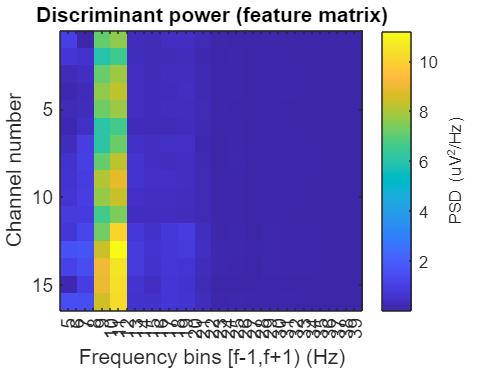

imagesc([5 41],yy , discmatrix')
xlabel('Frequency bins [f-1,f+1) (Hz)')
ylabel('Channel number')
title('Discriminant power (feature matrix)')
clh = colorbar;
ylabel(clh, 'PSD (uV^2/Hz)')
set(gca, 'XTick', [5:39]) % what should go here ?
xlim([4 40])

## Question 6

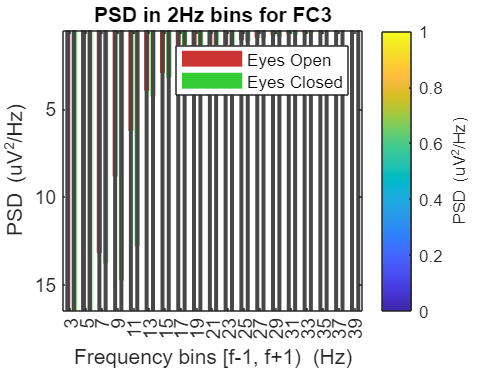

% set up frequency axis
xf_temp = reshape(freqs_eo(1:N_psd_eo), N_psd_ec/(Fs / (2 * 2)), []) + 1;  % N_psd_eo = N_psd_ec
                                                                           % freqs_eo = freqs_ec so does not matter which one to use
xf = xf_temp(1,:);

Ei = 2; % Choose your electrode here!

% plot mean and std dev  
h = superbar(xf, [eo_psd_2hz_mean(:,Ei) ec_psd_2hz_mean(:,Ei)], 'E', [eo_psd_2hz_std(:,Ei)
ec_psd_2hz_std(:,Ei)]);

% Colour the groups and add legend (avoiding bug in superbar grouping)
Colours = [.8 .2 .2;
     .2 .8 .2];
for iBarSeries = 1:length(eo_psd_2hz_mean)
    set(h(iBarSeries, 1), 'FaceColor', Colours(1, :), 'EdgeColor', 'none');
    set(h(iBarSeries, 2), 'FaceColor', Colours(2, :), 'EdgeColor', 'none');
end
legend([h(1,1) h(1,2)], 'Eyes Open', 'Eyes Closed');

% Add labels and set axes limits

str_title = cell2mat(strcat({'PSD in 2Hz bins for '}, electrode_labels{Ei}));
title(str_title)
xlim([2,40])
set(gca, 'XTick', 1:2:39)
%ylim([1,16])
ylabel('PSD (uV^2/Hz)')
%set(gca, 'YTick', 'reverse')
xlabel('Frequency bins [f-1, f+1)  (Hz)')

## Question 8

% Pick two features and construct your training data from all your epochs
eo_features(:, 1:2) = eo_psd_2hz(5:6,:,Ei)';
ec_features(:, 1:2) = ec_psd_2hz(5:6,:,Ei)';
features = [eo_features; ec_features];
for i=1:N_epochs
 my_classes{i} = 'eyes open';
 my_classes{i+N_epochs} = 'eyes closed';
end
classes = my_classes';

## Question 9

% Plot the feature space (2 dimensions for now)
gscatter(features(:,1), features(:,2), classes,'rb','od');
xlabel('8-10Hz power @ FC3 (uV^2/Hz)');
ylabel('10-12Hz power @ FC3 (uV^2/Hz)');

% Linear Discriminant Analysis (LDA).
lda = fitcdiscr(features(:,1:2),classes);
ldaClass = resubPredict(lda)

ldaClass = 16×1 cell array
    {'eyes open'  }
    {'eyes open'  }
    {'eyes open'  }
    {'eyes open'  }
    {'eyes open'  }
    {'eyes open'  }
    {'eyes open'  }
    {'eyes open'  }
    {'eyes closed'}
    {'eyes closed'}
    {'eyes closed'}
    {'eyes closed'}
    {'eyes closed'}
    {'eyes closed'}
    {'eyes closed'}
    {'eyes closed'}



ldaResubErr = resubLoss(lda) %q11

ldaResubErr = 0

[ldaResubCM,grpOrder] = confusionmat(classes,ldaClass) %q12

ldaResubCM =      8     0
     0     8


grpOrder = 2×1 cell array
    {'eyes open'  }
    {'eyes closed'}


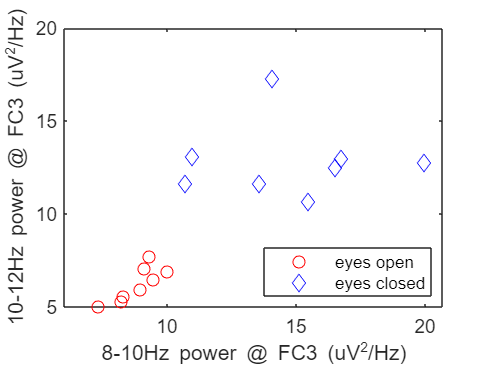

bad = ~strcmp(ldaClass,classes);  %q13
hold on;
plot(features(bad,1), features(bad,2), 'kx');
hold off;


[x, y] = meshgrid(6:1:20, 4:1:18)  % continutation of LDA: the function has seperated the plane into regions divided by lines, and assigned diffrent regions to different classes. One way to 

x =      6     7     8     9    10    11    12    13    14    15    16    17    18    19    20
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20
     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20


y =      4     4     4     4     4     4     4     4     4     4     4     4     4     4     4
     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5
     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6
     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7
     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8
     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9
    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10
    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11
    12    12    12    12    12    12    12    12    12    12    12    12    12    12    12
    13    13    13    13    13    13    13    13    13    13    13    13    13    13    13


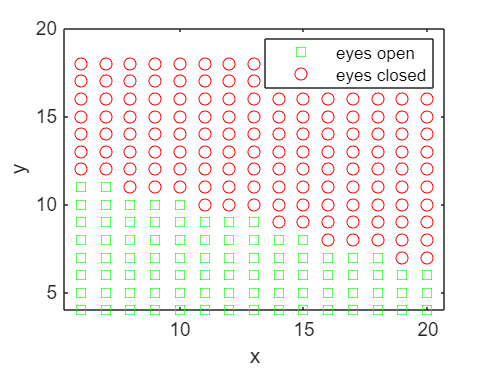

%visualize these regions is to create a grid of (x, y) values amd apply the
%classification function to that grid.
x = x(:);
y = y(:);
l = classify([x y], features(:, 1:2), classes);
gscatter(x, y, l, 'grb', 'sod')

% K-Fold cross validation for LDA
cp = cvpartition(classes,'KFold',5)

cp = K-fold cross validation partition
   NumObservations: 16
       NumTestSets: 5
         TrainSize: 13  12  13  13  13
          TestSize: 3  4  3  3  3

cvlda = crossval(lda,'CVPartition',cp)

cvlda =   ClassificationPartitionedModel
    CrossValidatedModel: 'Discriminant'
         PredictorNames: {'x1'  'x2'}
           ResponseName: 'Y'
        NumObservations: 16
                  KFold: 5
              Partition: [1×1 cvpartition]
             ClassNames: {'eyes closed'  'eyes open'}
         ScoreTransform: 'none'


  Properties, Methods


ldaCVErr = kfoldLoss(cvlda)

ldaCVErr = 0

% Naive Bayesian method
nbGau = fitcnb(features(:,1:2), classes)

nbGau =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: {'eyes closed'  'eyes open'}
            ScoreTransform: 'none'
           NumObservations: 16
         DistributionNames: {'normal'  'normal'}
    DistributionParameters: {2×2 cell}


  Properties, Methods


nbGauResubErr = resubLoss(nbGau)

nbGauResubErr = 0


nbGauCV = crossval(nbGau, 'CVPartition',cp)

nbGauCV =   ClassificationPartitionedModel
    CrossValidatedModel: 'NaiveBayes'
         PredictorNames: {'x1'  'x2'}
           ResponseName: 'Y'
        NumObservations: 16
                  KFold: 5
              Partition: [1×1 cvpartition]
             ClassNames: {'eyes closed'  'eyes open'}
         ScoreTransform: 'none'


  Properties, Methods


nbGauCVErr = kfoldLoss(nbGauCV)

nbGauCVErr = 0

labels = predict(nbGau, [x y])

labels = 225×1 cell array
    {'eyes open'  }
    {'eyes open'  }
    {'eyes open'  }
    {'eyes open'  }
    {'eyes open'  }
    {'eyes closed'}
    {'eyes closed'}
    {'eyes closed'}
    {'eyes closed'}
    {'eyes closed'}
    {'eyes closed'}
    {'eyes closed'}
    {'eyes closed'}
    {'eyes closed'}
    {'eyes closed'}
    {'eyes open'  }
    {'eyes open'  }
    {'eyes open'  }
    {'eyes open'  }
    {'eyes open'  }
    {'eyes open'  }
    {'eyes closed'}
    {'eyes closed'}
    {'eyes closed'}
    {'eyes closed'}
    {'eyes closed'}
    {'eyes closed'}
    {'eyes closed'}
    {'eyes closed'}
    {'eyes closed'}


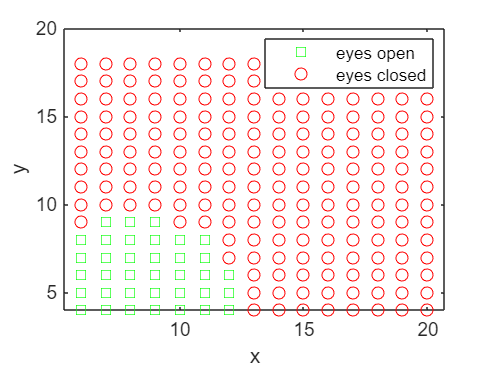

gscatter(x, y, labels, 'grb', 'sod')


% K-Fold cross validation for Naive Bayes
cp2 = cvpartition(classes, 'KFold', 5)

cp2 = K-fold cross validation partition
   NumObservations: 16
       NumTestSets: 5
         TrainSize: 13  12  13  13  13
          TestSize: 3  4  3  3  3

cvnbGau = crossval(nbGau, 'CVPartition', cp2)

cvnbGau =   ClassificationPartitionedModel
    CrossValidatedModel: 'NaiveBayes'
         PredictorNames: {'x1'  'x2'}
           ResponseName: 'Y'
        NumObservations: 16
                  KFold: 5
              Partition: [1×1 cvpartition]
             ClassNames: {'eyes closed'  'eyes open'}
         ScoreTransform: 'none'


  Properties, Methods


nbGauCVErr = kfoldLoss(cvnbGau)

nbGauCVErr = 0

## Question 15

% obtain the ROC by cross-validation:
[LDALabel, LDAScore] = kfoldPredict(cvlda);
[FPR, TPR, Thr, AUC, OPTROCPT] = perfcurve(classes, LDAScore(:,1), 'eyes closed')

FPR =          0
         0
         0
         0
         0
         0
         0
         0
         0
    0.1250


TPR =          0
    0.1250
    0.2500
    0.3750
    0.5000
    0.6250
    0.7500
    0.8750
    1.0000
    1.0000


Thr =     1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.9986
    0.9967
    0.9939
    0.9697
    0.0006


AUC = 1

OPTROCPT =      0     1


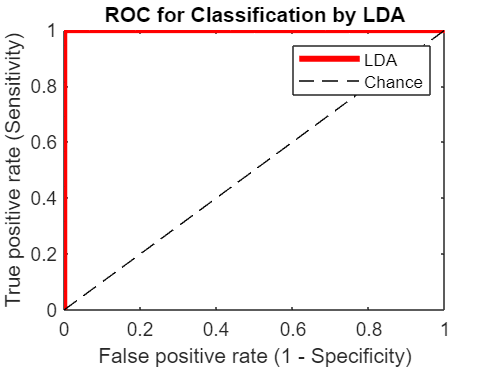

figure
plot(FPR, TPR, 'r', 'linewidth', 3)
hold on
plot ([0 1], [0 1], '--k')
xlabel('False positive rate (1 - Specificity)')
ylabel('True positive rate (Sensitivity)')
title('ROC for Classification by LDA')
legend('LDA', 'Chance')


% resp = strcmp(classes, 'b')
% pred = features(:, 1:2);
% mdl = fitglm(pred, resp, 'Distribution', 'binomial', 'Link', 'logit');
% score_log = mdl.FittedProbability
% [Xlog, Ylog, Tlog, AUClog] = perfcurve(resp, score_log, 'true');

nbGau = fitcnb(features(:,1:2), classes)

nbGau =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: {'eyes closed'  'eyes open'}
            ScoreTransform: 'none'
           NumObservations: 16
         DistributionNames: {'normal'  'normal'}
    DistributionParameters: {2×2 cell}


  Properties, Methods


[~,score_nb] = resubPredict(nbGau)

score_nb =     0.0001    0.9999
    0.0014    0.9986
    0.0002    0.9998
    0.0038    0.9962
    0.0005    0.9995
    0.0000    1.0000
    0.0000    1.0000
    0.0000    1.0000
    1.0000    0.0000
    1.0000    0.0000


[X,Y,Tnb,AUCnb, OPTROCPTnb] = perfcurve(classes, score_nb(:,1),'true')

Error using perfcurve>membership (line 705)
Positive class is not found in the input data.

Error in perfcurve (line 449)
[W,subYnames] = membership(cls(sorted),weights(sorted),...



plot(FPR,TPR)
plot(Xnb,Ynb)
legend('Linear Discriminant Analysis','Naive Bayes','Location','Best')
xlabel('False positive rate'); ylabel('True positive rate');
title('ROC Curves for Linear Discriminant Analaysis and Naive Bayes Classification')
hold off